# Analyse des Signaux

TD5 - Signal Processing Toolbox

14/12/22

8;

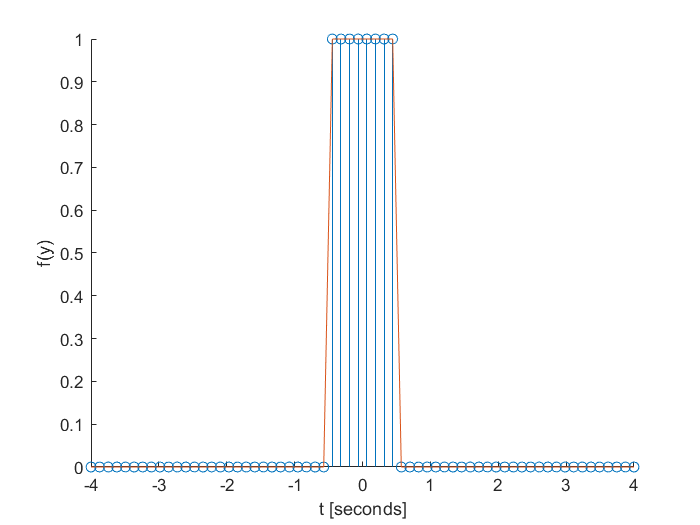

clc; clear all; close all;

fe = 8;
n_points = 64;
interval = 4;

t = linspace(-interval,interval,n_points);
y = [zeros(1,(n_points - fe)/2), ones(1,fe), zeros(1,(n_points - fe)/2)];
figure; hold on;
stem(t,y); plot(t,y)
xlabel("t [seconds]"); ylabel("f(t)")

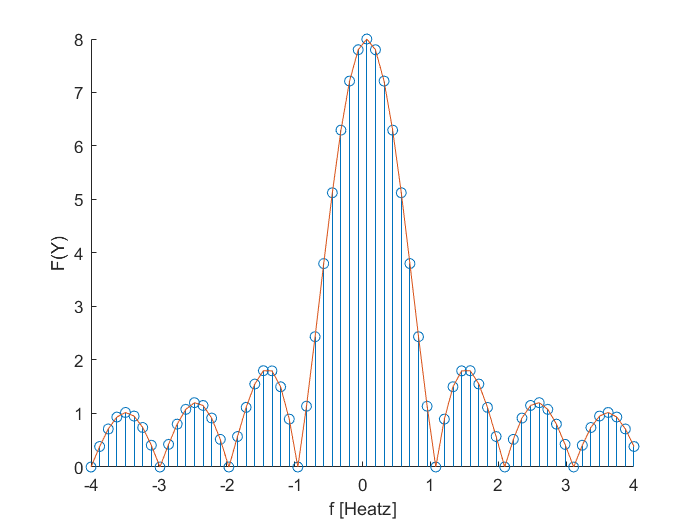

Y = fftshift(abs(fft(y)));
figure; hold on;
stem(t,Y); plot(t,Y)
xlabel("f [Heatz]"); ylabel("F(Y)")

Expliquer les différences (repliement de spectre, effet de fenêtrage)

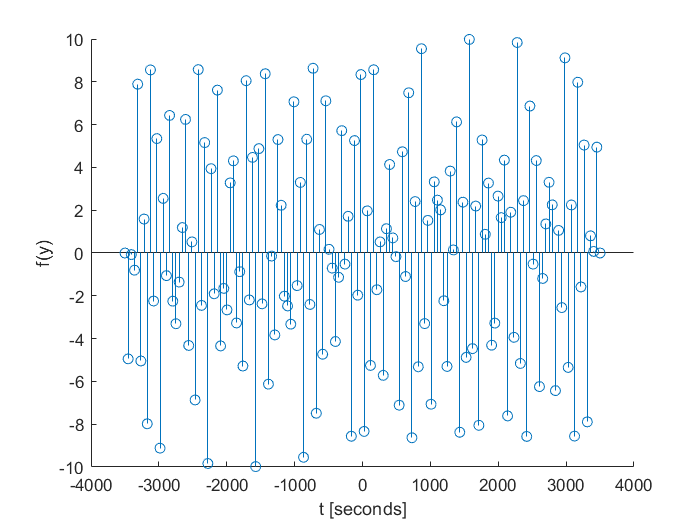

clc; clear all; close all;

interval = 3500;
%fe = 7000;
n_points = 150;

t = linspace(-interval,interval,n_points);
j = 4*sin(2*pi*1500*t) + 6*sin(2*pi*3500*t);
figure; hold on;
stem(t,j); %plot(t,j)
xlabel("t [seconds]"); ylabel("f(y)")

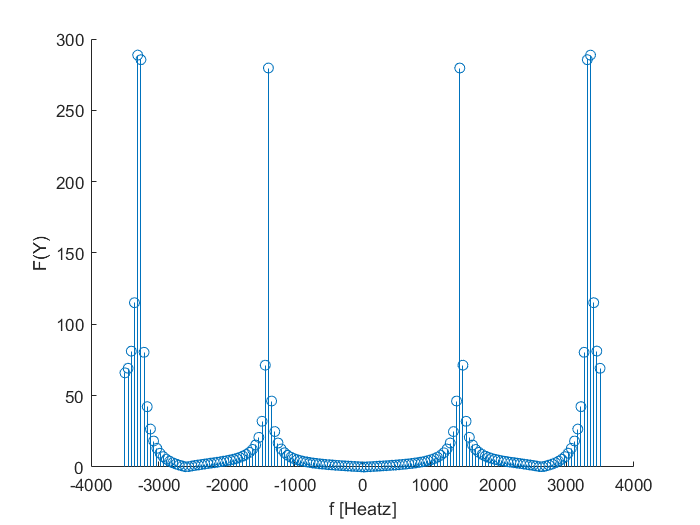

J = fftshift(abs(fft(j)));
figure; hold on;
stem(t,J); %plot(t,J)
xlabel("f [Heatz]"); ylabel("F(Y)")

b = importfile("mesure.dat");
disp(b(1))

    mesure: [2×1024 double]



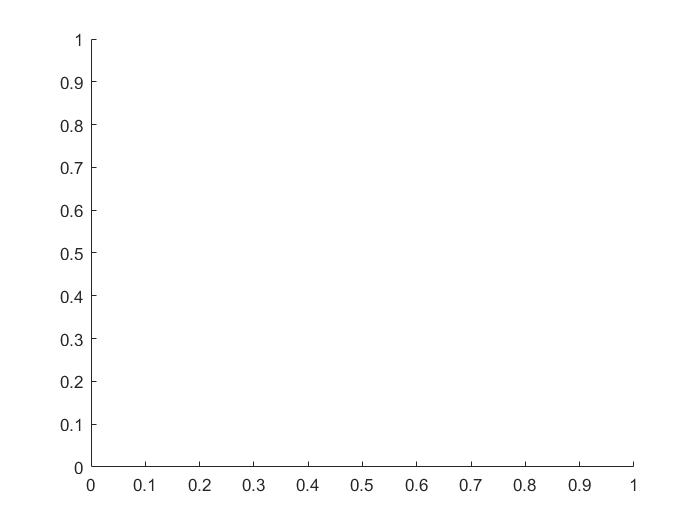




B = fft(x);

figure; hold on;

stem(b(1),b(2)); plot(b(1),b(2))

Index exceeds the number of array elements (1).

xlim([-1,1]); ylim([0,1.5])
xlabel("t [seconds]"); ylabel("f(y)")
